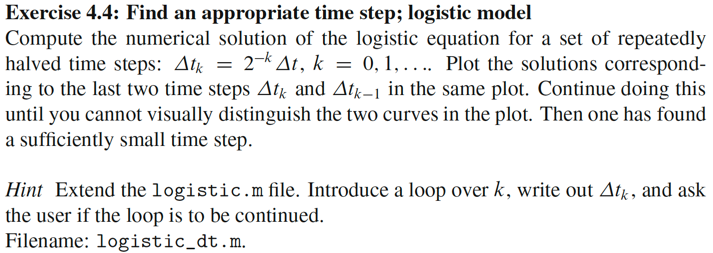

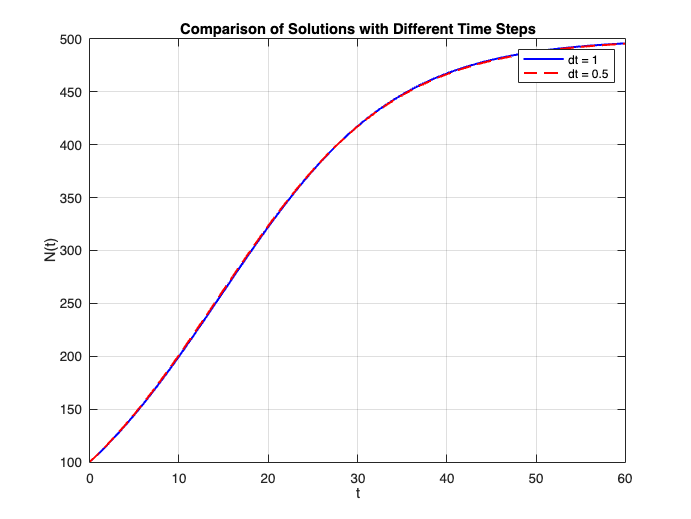

%given parameters
f = @(u, t) 0.1 * (1 - u / 500) * u; %definition of function
U_0 = 100;
T = 60;     %end time

%define the first two timesteps
dt1 = 2^0; 
dt2 = 2^(-1);

%solve with dt1
[u1, t1] = ode_FE(f, U_0, dt1, T);

%solve with dt2
[u2, t2] = ode_FE(f, U_0, dt2, T);

%make plot
figure;
plot(t1, u1, 'b-', 'LineWidth', 1.5);
hold on;
plot(t2, u2, 'r--', 'LineWidth', 1.5);
xlabel('t');
ylabel('N(t)');
legend(['dt = ', num2str(dt1)], ['dt = ', num2str(dt2)]);
title('Comparison of Solutions with Different Time Steps');
grid on;
hold off;

Jeg kan, allerede efter første iteration ikke se forskel på de to grafer og øvelsen stopper derfor ret tidligt. 